# Competing Species

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

The populations of two competing species, cheetahs (*x*) and lions (*y*), are described by the system:

*d**x**d**t*=*x/*1000(1000−*x*−0.8*y*)

*d**y**d**t*=*y/*500(500−0.15*x*−*y*)

Their equilibrium population levels can be found by solving the nonlinear system of equations:

*x/*1000(1000−*x*−0.8*y*)=0

*y/*500(500−0.15*x*−*y*) =0

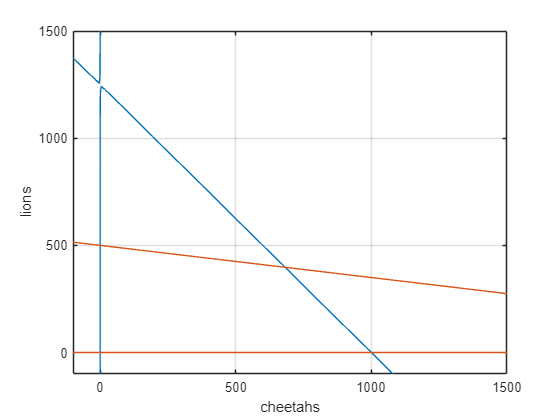

dx = @(x, y) (x/1000).*(1000 - x - .8*y);
dy = @(x, y) (y/500).*(500 - .15*x - y);

fimplicit(dx, [-100, 1500])
hold on
fimplicit(dy)
hold off
grid on
xlabel("cheetahs")
ylabel("lions")

## Task 2

rootFunction = @(w) [dx(w(1), w(2)); dy(w(1), w(2))];
w0 = [600; 300];
popRoot = fsolve(rootFunction, w0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


popRoot =   681.8182
  397.7273
